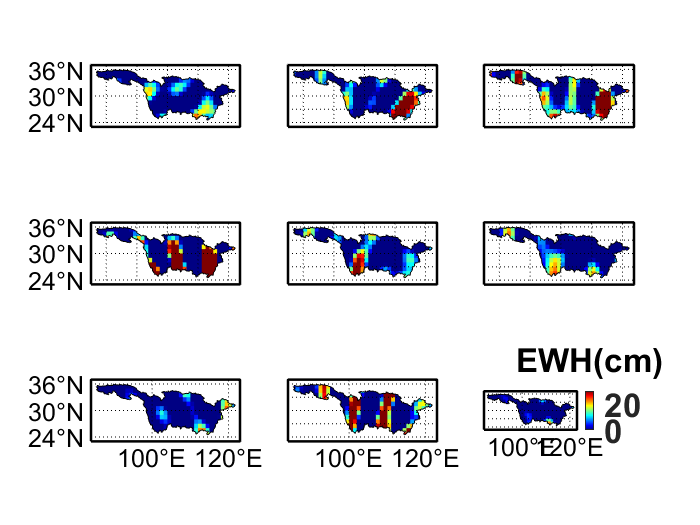

clearvars -except grid_CSR;
close all;
addpath E:\TCH
addpath E:\Data\result\grid

load grid_CSR.mat;%以CSR机构的数据产品为例
[M,N,~]=size(grid_CSR);num=9;%月份选取数据的前9个月进行展示说明
%读取长江流域边界的经纬度信息
[lon,lat] = textread('E:\TCH\Yangtze.txt','%f %f','delimiter',',','headerlines',1);
%确定边界经纬度的最值，根据最值确定画图范围
lonmax=ceil(max(lon));latmax=ceil(max(lat));
lonmin=floor(min(lon));latmin=floor(min(lat));
Yangtze=grid_CSR((90-latmax-1):(90-latmin+1),(lonmin-1):(lonmax+1),1:num);

%设置两个掩膜的闭合区域
lontmp1 = [88;lon(1:6000);123;123;84;84;88];lattmp1 = [23;lat(1:6000);23;37;37;23;23];
lontmp2 = [123;lon(6000:end);88;123];lattmp2 = [23;lat(6000:end);23;23];

K=9;
% figure(1);
for k=1:K
subplot(3,3,k)
[LON,LAT] = meshgrid((lonmin-1:1:lonmax+1),(latmax+1:-1:latmin-1));
yangtze(:,:)=Yangtze(:,:,k).*100;
m_proj('Equidistant Cylindrical','long',[lonmin-1,lonmax+1],'lat',[latmin-1,latmax+1]);
m_pcolor(LON,LAT,yangtze); %绘制假彩色图像preseucolor
shading flat;
hold on
h1=m_patch(lontmp1,lattmp1,'white','EdgeColor','w');%掩膜贴片一
h2=m_patch(lontmp2,lattmp2,'white','EdgeColor','w');%掩膜贴片二
m_plot(lon,lat,'k');
if k==7
     m_grid('xtick',3,'ytick',3,'tickdir','in','xlabeldir','middle',...
    'TickLength',0.008,'LineWidth',1.5,'FontName', 'Helvetica','FontSize',15,'fontweight','bold');
elseif  k==8 || k==9
     m_grid('xtick',3,'yticklabels',[],'tickdir','in','xlabeldir','middle',...
    'TickLength',0.008,'LineWidth',1.5,'FontName', 'Helvetica','FontSize',15,'fontweight','bold');
elseif  k==1 || k==4
     m_grid('xticklabels',[],'ytick',3,'tickdir','in','xlabeldir','middle',...
    'TickLength',0.008,'LineWidth',1.5,'FontName', 'Helvetica','FontSize',15,'fontweight','bold');
else
m_grid('xticklabels',[],'yticklabels',[],'tickdir','in','xlabeldir','middle',...
    'TickLength',0.008,'LineWidth',1.5,'FontName', 'Helvetica','FontSize',15,'fontweight','bold');
end
caxis([0,30]);colormap('jet');
    if k==K
        h=colorbar('v','FontSize',20,'fontweight','bold');
        set(get(h,'title'),'string','EWH(cm)','FontSize',20,'fontweight','bold');
    end
end